Система 

A = [-9, 31, -22, 15;
    0, -6, 4, 0;
    0, -10, 6, 0;
    -6, 17, -13, 9];
B = [3, 0;
    -1, 0;
    -2, 0;
    2, 0];
D = [0, 0;
    0, 5];
x0 = [1;2;3;4];
x0T = x0';

Пара Q, R

Q = [16, 0, 0, 0;
    0, 16, 0, 0;
    0, 0, 16, 0;
    0, 0, 0, 16];
R = [4,0;
    0, 4];

Проверка пары A B на стабилизируемость

U = ctrb(A, B);
rankU = rank(U);

Проверка пары Q A на обнаруживаемость

U = obsv(Q, A);
rankU = rank(U);

Решение уравнения Риккати

M = -B*inv(R)*B';

[P,K1,L1] = icare(A,[],Q,[],[],[],M);

K = -inv(R)*B'*P

K =    -2.3761   -7.0694    5.9733    0.0160
         0         0         0         0


J = round(x0'*P*x0)

J = 2422

Построение графиков 

plot(out.u, 'LineWidth', 2);
title('u(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$u_{1}$(t)","$u_{2}$(t)","$u_{3}$(t)","$u_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);

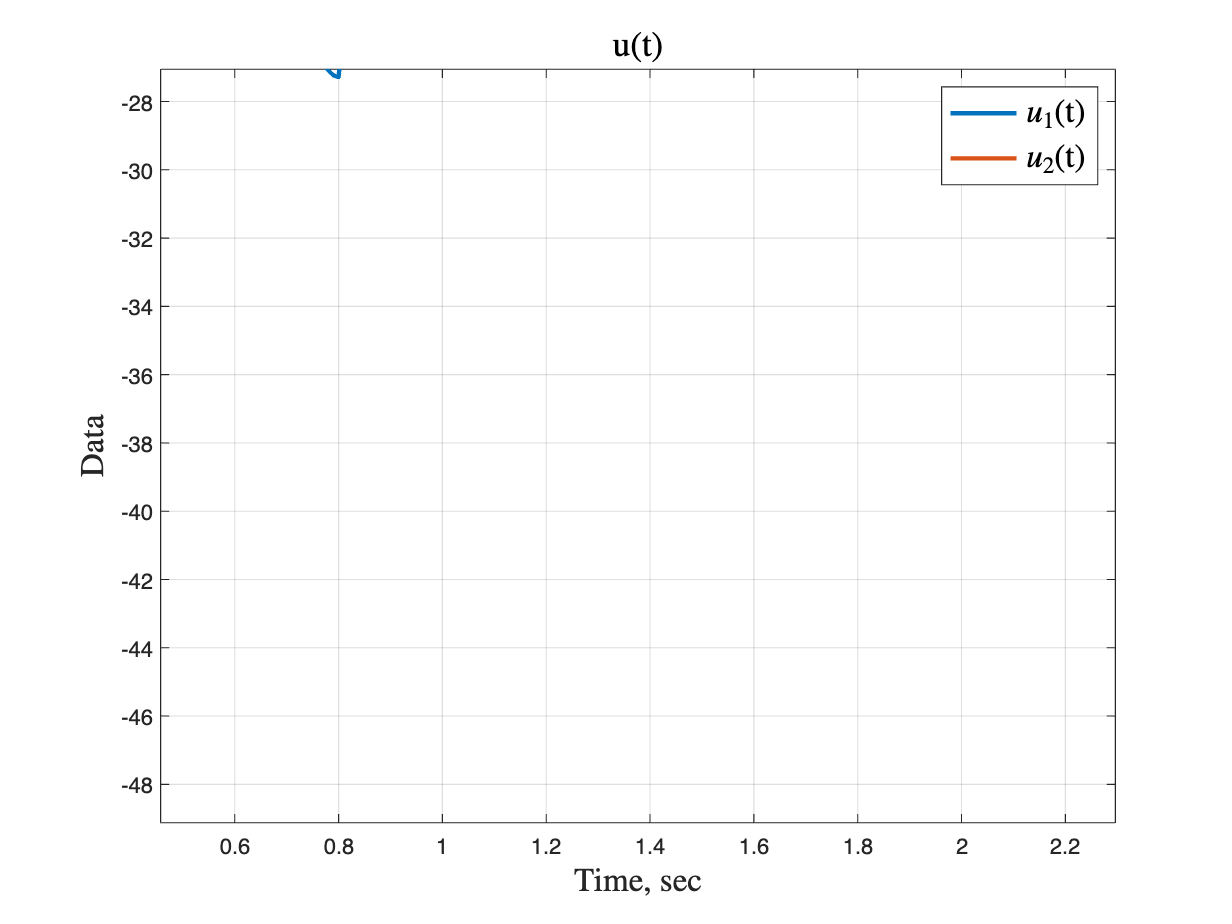

grid on;
hold off;

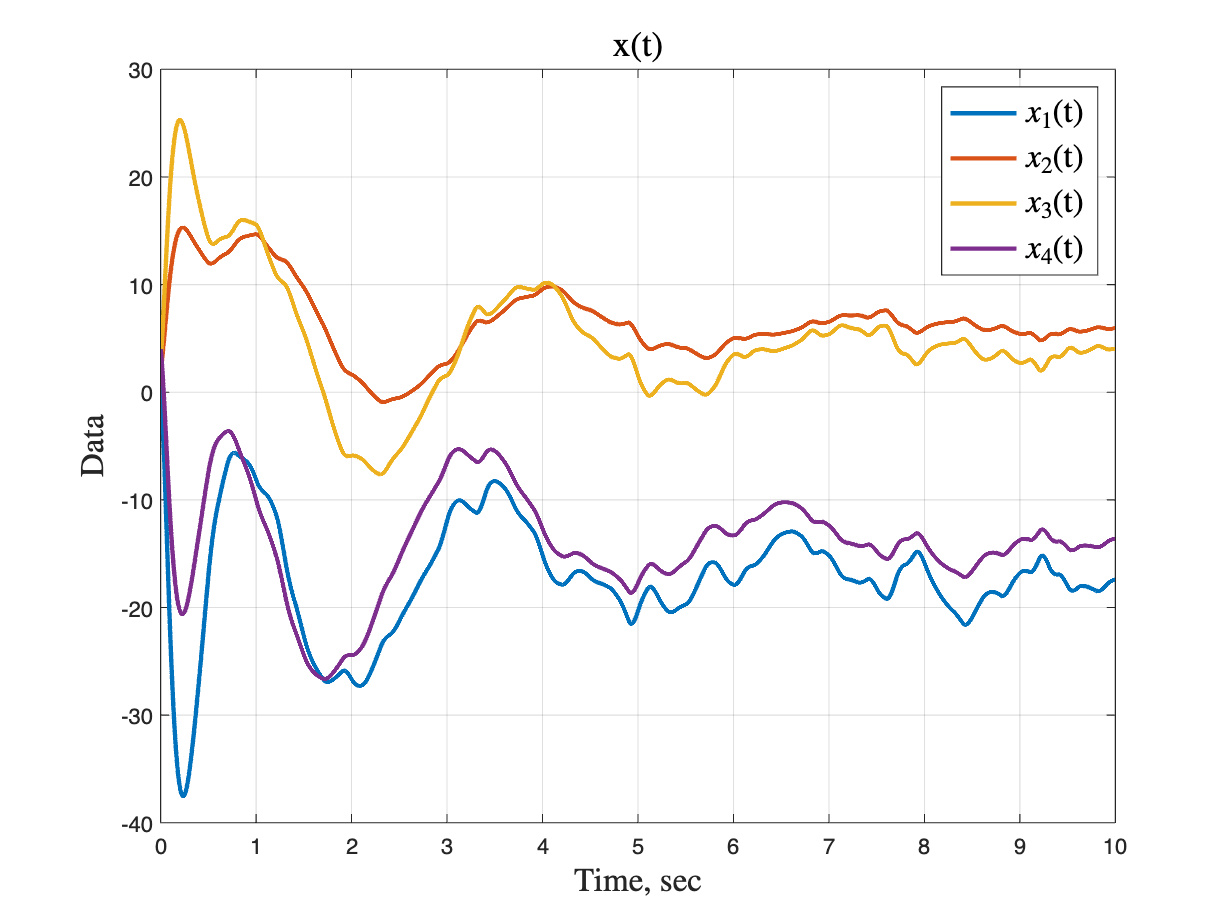


plot(out.x, 'LineWidth', 2);
title('x(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$x_{2}$(t)","$x_{3}$(t)","$x_{4}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;


plot(out.J, 'LineWidth', 2);

Unrecognized field name "J".

title('J(t)','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;